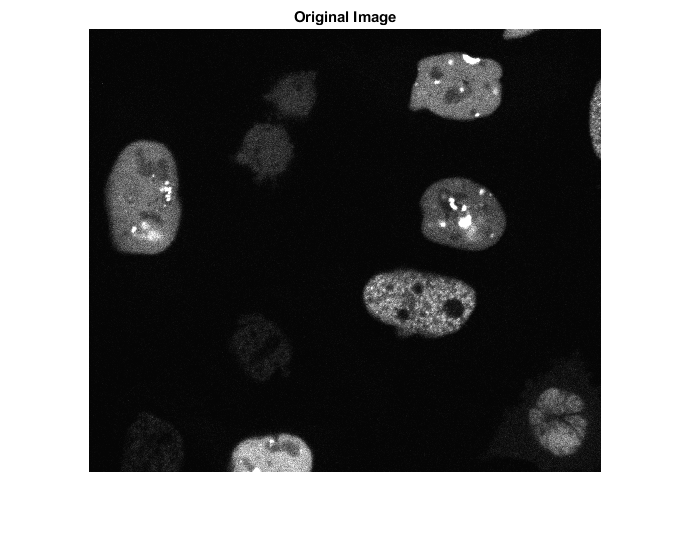

% Implementation of Phase Stretch Transform (PST) in Matlab
% Derived from work of: M. Asghari and Madhuri Suthar, Jalali Lab, Department of Electrical and Computer Engineering,  UCLA

clc  % clear screen
clear all  % clear all variables
close all   % close all figures
addpath('src/'); % script source directory

% New image loading
cell_dataset = cell_dataset('data/Fluo-N3DH-CHO/01/');
% implay(dataset(:,:,1,:), 4);

% Work with a single 3D image for now
Image_orig = cell_dataset(:,:,:,1);

% Repeat the Z axis by 5x, since the voxels are not even in X/Y/Z
% Voxel size (microns): 0.202 x 0.202 x 1.0
% Repeating Z axis by 5x should make the voxel size 0.202 x 0.202 x 0.2
% (good enough)
Image_orig = repelem(Image_orig, 1, 1, 5);

%show the original image
%subplot(1,2,1)
%Image_orig = im2double(Image_orig(:,:,:));
imshow(Image_orig(:,:,1))
title('Original Image') % convert the grayscale image do a 2D double array

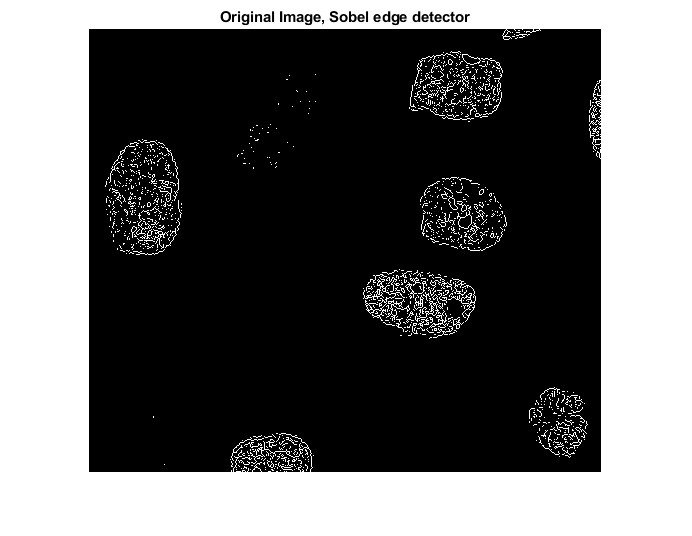

%Image_orig=double(Image_orig);

% MK: Show edges using 1st order Sobel edge detector kernel
figure;
edge(Image_orig(:,:,1), 'sobel');
title('Original Image, Sobel edge detector');

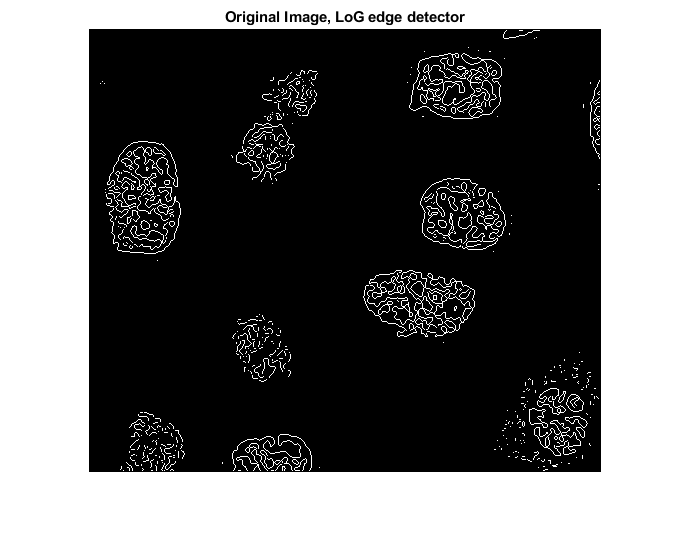

figure;
edge(Image_orig(:,:,1), 'log');
title('Original Image, LoG edge detector');

figure;

% low-pass filtering (also called localization) parameter
handles.LPF=0.2; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)

% PST parameters
handles.Phase_strength=0.48;  % PST  kernel Phase Strength
handles.Warp_strength=12.48;  % PST Kernel Warp Strength

% Thresholding parameters (for post processing)
handles.Thresh_min=-1;  % minimum Threshold  (a number between 0 and -1)
handles.Thresh_max= 0.0019;  % maximum Threshold  (a number between 0 and 1)
handles.Thresh_dark = 1/9; % dark threshold (between 0 and 1)

% Apply PST and find features (sharp transitions)
% [Edge, PST_Kernel]= PST(Image_orig,handles,Morph_flag);
[features, PST_Kernel] = PST_ND(Image_orig, handles);
[edge] = PST_post(Image_orig, features, handles);


% MK: Best edges on Z layer 21
refined_edge = edge(:,:,21:25);

% Show and save 'analog' edge output
filename = 't000.tif';
figure;
features_img = features(:,:,1)/max(features, [], 'all')*3

features_img =    -0.1240   -0.2739   -0.1165   -0.1265   -0.2475   -0.1174   -0.0315   -0.1611   -0.2864   -0.2909   -0.1651   -0.1097   -0.0460   -0.0507   -0.1753   -0.1582   -0.0332   -0.0429   -0.0937   -0.0806   -0.0871   -0.0510   -0.0243   -0.0203   -0.0374   -0.0964   -0.0589   -0.0086   -0.0009    0.0557   -0.0249   -0.1058    0.0233    0.2076    0.1722    0.0111    0.0082    0.0189    0.0590    0.0201    0.0009   -0.0344   -0.1807   -0.0977    0.0498    0.1762    0.0674   -0.0357    0.1936    0.2372
   -0.2888   -0.3289   -0.1797   -0.1690   -0.2447   -0.1755   -0.1857   -0.2779   -0.1975   -0.1418   -0.1042   -0.0717   -0.0356   -0.0304   -0.0201    0.0062   -0.0498   -0.1996   -0.2396   -0.1207   -0.0718   -0.1043   -0.1290   -0.0961   -0.0479   -0.1789   -0.2322   -0.1140   -0.1163   -0.0697   -0.0038    0.0777    0.1689    0.1741    0.1008    0.0745    0.1303    0.0425    0.0593    0.1842    0.1531   -0.0181   -0.1020    0.0210   -0.0498    0.0023    0.0547    0.0745    

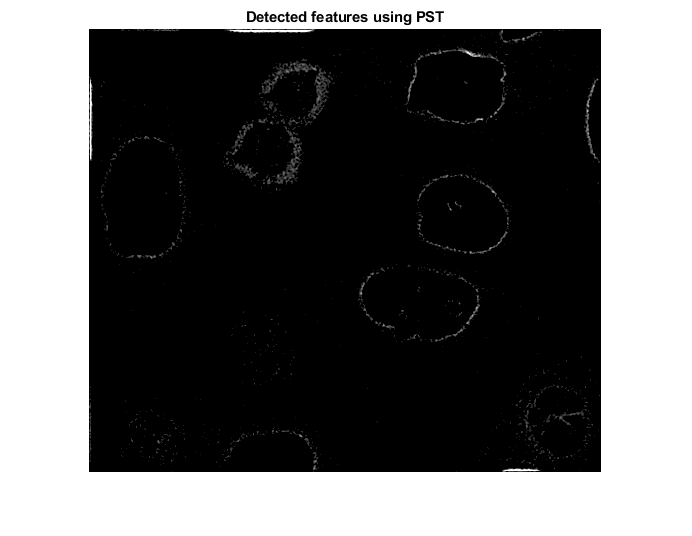


% Post proccess features_img
features_img(features_img < 0) = 0;
features_img(features_img < 0.1) = 0;

%Attempt to find centroids of blobs
cc = bwconncomp(features_img, 26);
stats = regionprops(cc, 'Centroid');
start_cents = [];
for i = 1:size(stats, 1)
    start_cents = [start_cents ; stats(i).Centroid];
end
prev_size = size(start_cents, 1);
true_centroids = centroid_reduction(start_cents, 50);
curr_size = size(true_centroids, 1);
while prev_size ~= curr_size
    true_centroids = centroid_reduction(true_centroids, 110);
    prev_size = curr_size;
    curr_size = size(true_centroids, 1);
end

imshow(features_img)
title('Detected features using PST')

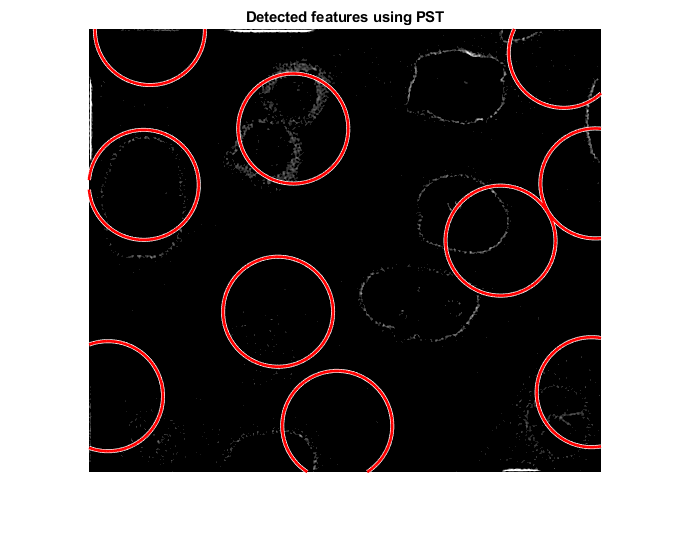

file_and_extension = strsplit(filename,'.');
output_path = char(strcat('data/Test_Images/',file_and_extension(1),'_features.tif'));
imwrite(features_img, output_path);

% Show and save thresholded edges
figure;
imshow(features_img(:,:,1));
radii = ones(size(true_centroids, 1), 1) * 55;
viscircles(true_centroids(:,[1,2]), radii);
title('Detected features using PST')

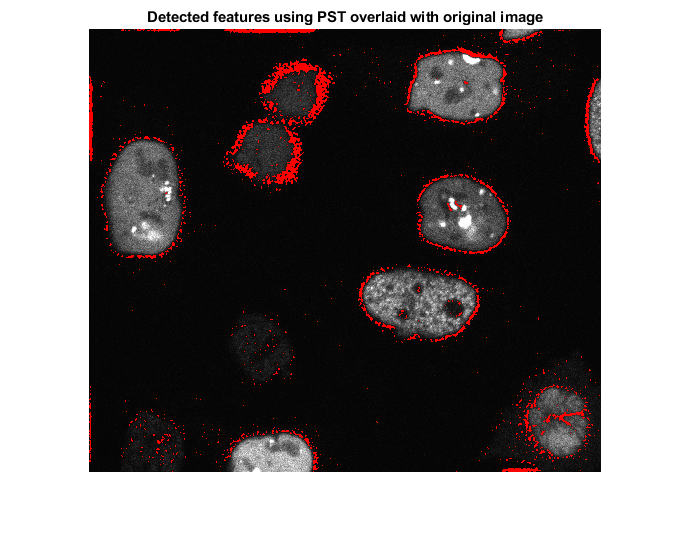

% save the image
file_and_extension=strsplit(filename,'.');
output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_edge.tif'));
imwrite(edge(:,:,1), output_path);
% overlay original image with detected features
overlay = imoverlay(Image_orig, abs(features_img(:,:,1)), [1 0 0]);
figure;
%imshow(overlay/max(overlay, [], 'all'));
imshow(overlay);
title('Detected features using PST overlaid with original image')

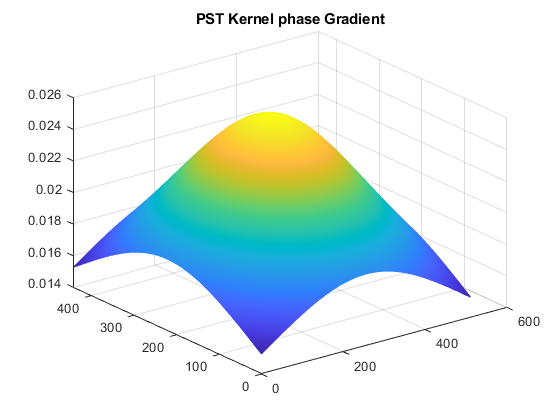

% save the image
output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_overlay.tif'));
imwrite(overlay/max(overlay, [], 'all'), output_path);

% show the PST phase kernel gradient
figure;
[D_PST_Kernel_x, D_PST_Kernel_y, D_PST_Kernel_z]=gradient(PST_Kernel);
mesh(sqrt(D_PST_Kernel_x(:,:,1).^2+D_PST_Kernel_y(:,:,1).^2+D_PST_Kernel_z(:,:,1).^2));
title('PST Kernel phase Gradient');